digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
'IncludeSubfolders',true,'LabelSource','foldernames');

% Number of images taken for each class (from 0 to 1000)
numTrainFiles = 200;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

tr_in = readall(imdsTrain);
tr_tg = imdsTrain.Labels;

addpath('NeuralODE', 'ContinuousReservoirComputing', 'DiscreteReservoirComputing', 'ODESolver');

% Initialize the Network
hidden_dim = 784;
omega_b = 0.5;
T = 0;
%f = @(bias, hidden_weights, hidden) (hidden_weights*hidden + bias);
eps = 0.01;
ode_solver = ODESolver(eps);
phi = @ode_solver.eulerForward;
eigs = {[0 10], ones(1, hidden_dim/2)};
ws = 0;
lambda_r = 0.1;
%Nl = 1;
seed = 1;

%net = NeuralODE(hidden_dim, omega_b, T, f, phi, eps, eigs, ws, lambda_r, seed);
net = NeuralODE(hidden_dim, omega_b, T, phi, eps, eigs, ws, lambda_r, seed);

% Fit
net = net.fitIC2classify(tr_in,tr_tg);

Accuracy: 99.95%
Accuracy: 98.05%
Accuracy: 95.5%
Accuracy: 99.85%
Accuracy: 100%
Accuracy: 100%
Accuracy: 100%
Accuracy: 100%
Accuracy: 100%
Accuracy: 100%


% Predict
pred_tr = net.classify(tr_in);

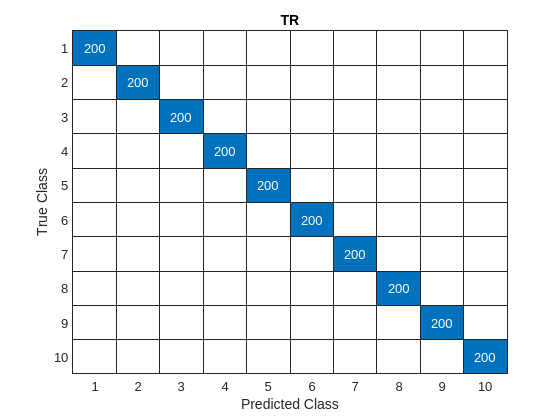

% Confusion Matrix
net.confusionMatrix(tr_in,tr_tg);
title("TR")

hidden = net.hiddenState(tr_in);

class = 9;
file = 23;
hidden_sample = hidden{file + class*numTrainFiles};
% Reshape to sequence of images
hidden_sample = reshape(hidden_sample,[sqrt(hidden_dim),sqrt(hidden_dim),size(hidden_sample,2)]);

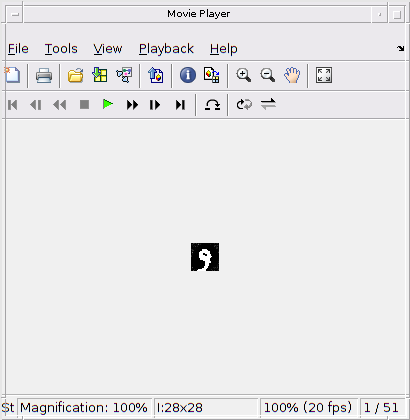

% Play video
implay(hidden_sample)